vid=VideoReader("PulsVid.mp4");
fil = load("PulsData.txt");

R=transpose(fil(:,1));
G=transpose(fil(:,2));
B=transpose(fil(:,3));
R=R-mean(R);
G=G-mean(G);
B=B-mean(B);

fps=vid.FrameRate;
N=length(R);
t=0:1/fps:(N-1)/fps;

R=highpass(R,40/60,fps); %Fjerner komponenter/frekvenser under 40 BPM
R=lowpass(R,230/60,fps) %Fjerner komponenter/frekvenser over 230 BPM

R =    -0.5514   -1.2320   -1.5281   -1.0984   -0.2841    0.2269    0.2202    0.2273    0.8296    1.8369    2.4176    2.0483    1.0903    0.3124    0.0419   -0.0039   -0.1759   -0.4891   -0.7831   -0.9778   -0.9929   -0.6333    0.1329    0.8389    0.7983   -0.1329   -1.2625   -1.7028   -1.2123   -0.2811    0.4789    0.8074    0.7566    0.5232    0.4155    0.6811    1.1131    1.0212   -0.0436   -1.5513   -2.3280   -1.7812   -0.5518    0.2397    0.1888   -0.2033   -0.3367   -0.0781    0.4852    1.3386



h=transpose(hann(N));
N_fft=2^(14);
df=fps/N_fft

df = 0.0012

f=(-fps/2:df:fps/2-df)*60; % Frekvens i BPM
R_fft=abs(fftshift(fft(h.*R,N_fft))); % Amplituderespons
S_r=20*log10(R_fft/max(R_fft));
[r_RR,lag] = xcorr(R,R);
lag=lag/fps*60;

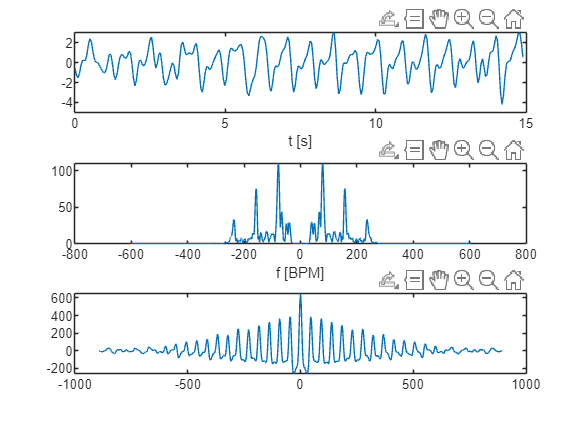

figure;

subplot(3,1,1);
plot(t,R);
xlabel("t [s]");

subplot(3,1,2);
plot(f,R_fft);
xlabel("f [BPM]");

subplot(3,1,3);
plot(lag,r_RR);

[~, puls_index] = sort(R_fft, 'descend'); % De 2 første verdiene vil gi x-verdi til de 2 største toppene

excluded = [puls_index(1), puls_index(2)]

excluded =         7124        9262


included = ~ismember(1:N_fft, excluded);
SNR_f=(R_fft(puls_index(1))+R_fft(puls_index(2)))/mean(R_fft(included));

disp("Puls: "+f(puls_index(2))+" BPM");

Puls: 78.5703 BPM


disp("SNR_f: "+SNR_f+" dB");

SNR_f: 33.7235 dB
